## 基本

気象庁の毎時潮位観測資料は，地点ごとおよび月ごとにファイルが分かれています．

このため，観測地点名・年・月を入力してインスタンスを生成し，変数の初期化を行います．

tidegauge = JMAtide('東京', 2019, 10)

tidegauge =   JMAtide のプロパティ:

              Station: '東京'
                 Year: 2019
                Month: 10
                 Time: []
                Ndays: []
                  SSH: []
           SSHanomaly: []
     AstronomicalTide: []
                  Lon: 139.7667
                  Lat: 35.6500
              URL_ssh: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/hry201910TK.txt'
             URL_ssha: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/dep201910TK.txt'
            URL_astro: 'https://www.data.jma.go.jp/kaiyou/data/db/tide/suisan/txt/2019/TK.txt'
    RefLevelObs_TP_cm: -188.4000
    RefLevelAst_TP_cm: -115
                 Unit: 'cm'
         StandardTime: 'JST(UTC+9)'
       ReferenceLevel: 'T.P.'


loadssh, loadssha でそれぞれ潮位，潮位偏差を気象庁ウェブサイトから取得します．

格納されるプロパティ名は SSH と SSHanomaly です．

tidegauge = tidegauge.loadssh; % 潮位
tidegauge = tidegauge.loadssha; % 潮位偏差

plotssh，plotssha で取得したデータの簡易的なプロットが可能です．

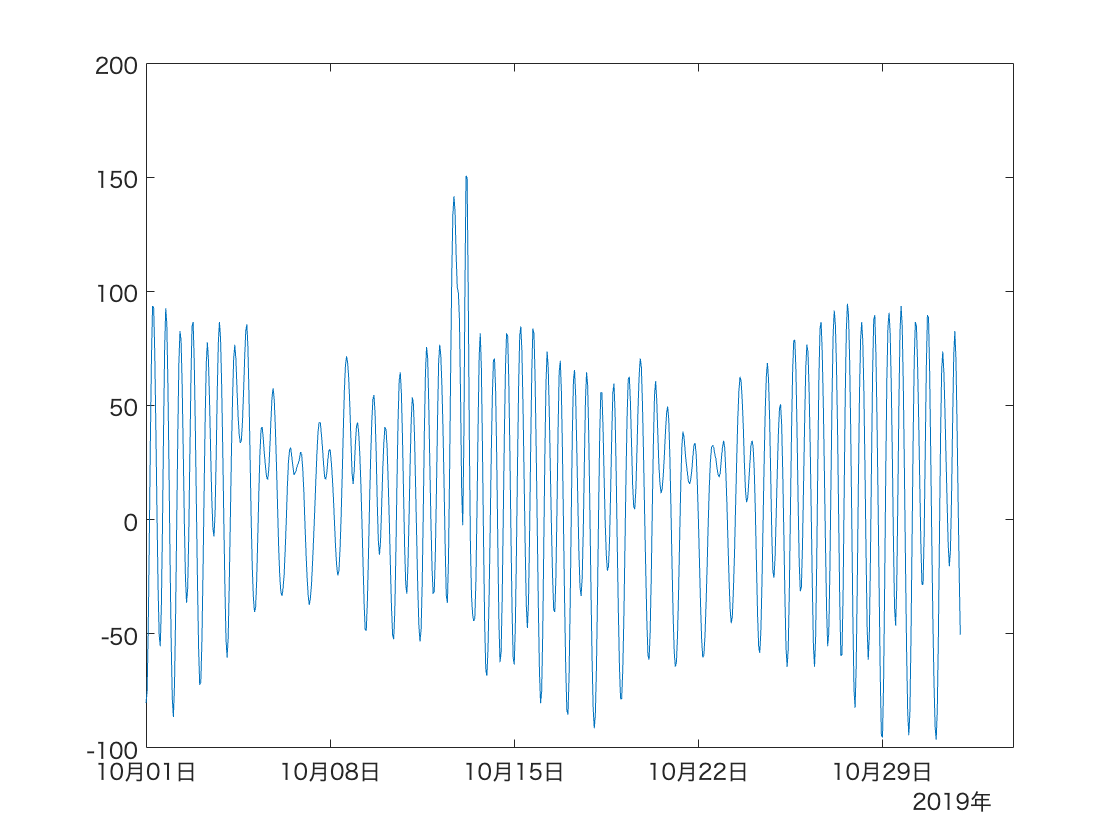

% 潮位のプロット
tidegauge.plotssh;

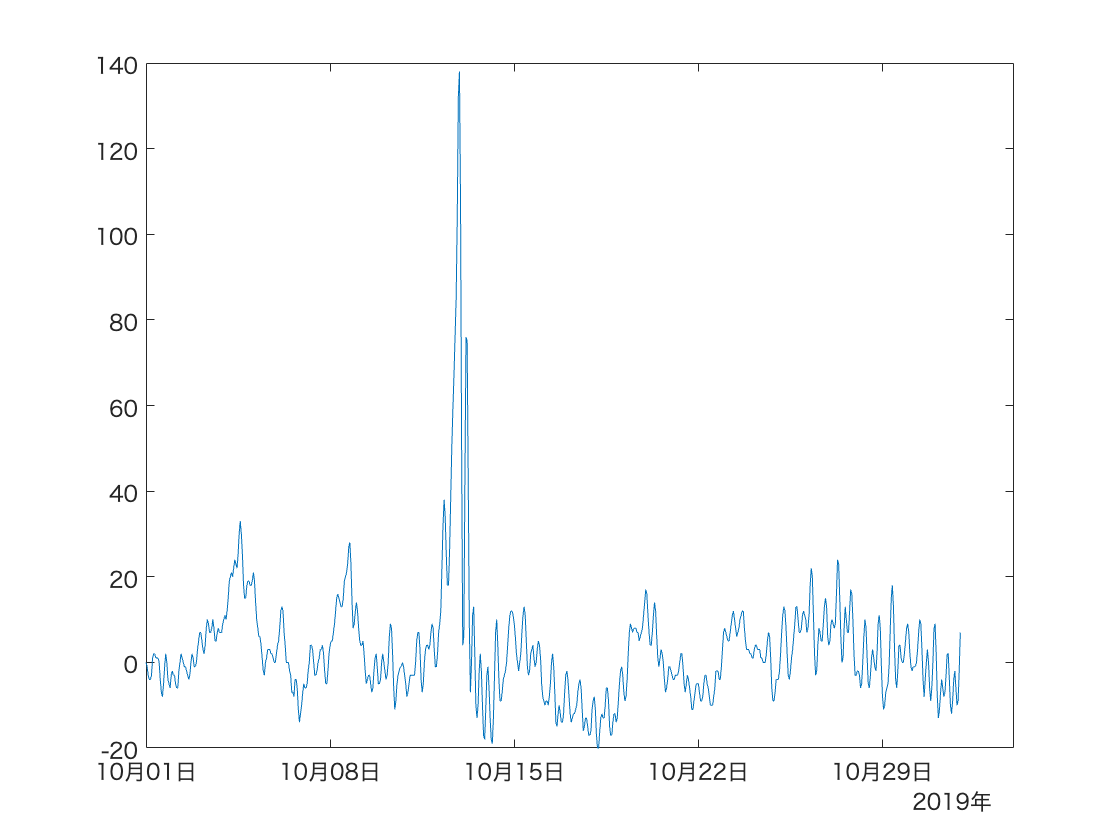

% 潮位偏差のプロット
tidegauge.plotssha;

## 長期（２ヶ月以上）のデータ取得

年月の指定部分に配列を入力することで，長期間の潮位データを対象とすることが可能です．

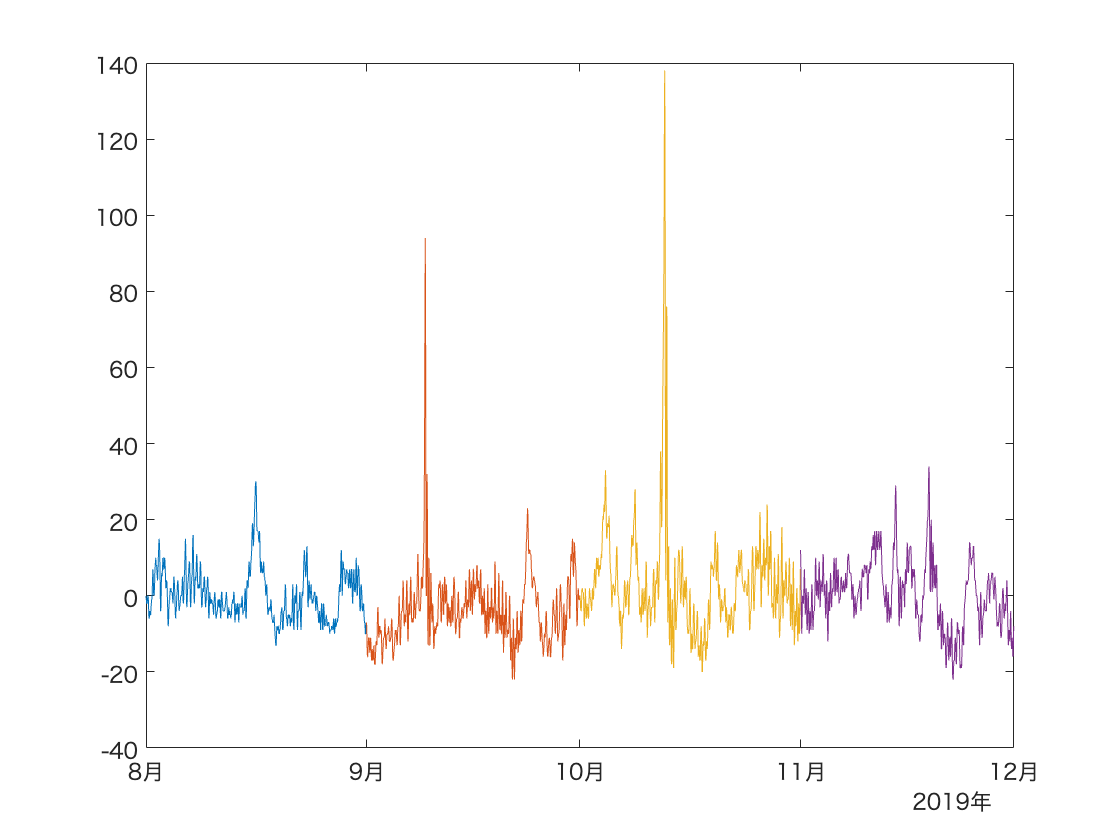

tidegauge = JMAtide('東京', 2019); % 2019年1月〜12月, (1x12)配列
tidegauge = JMAtide('東京', [2018,09; 2019,10]); % 2018年9月 と 2019年10月, (1x2)配列
tidegauge = JMAtide('東京', 2019, 8:11) % 2019年9月〜11月, (1x4)配列
tidegauge = tidegauge.loadssha;
tidegauge.plotssha;

## 複数地点のデータ取得

地点名を cell 配列で複数指定すると，複数地点の潮位データを同時に扱えます．

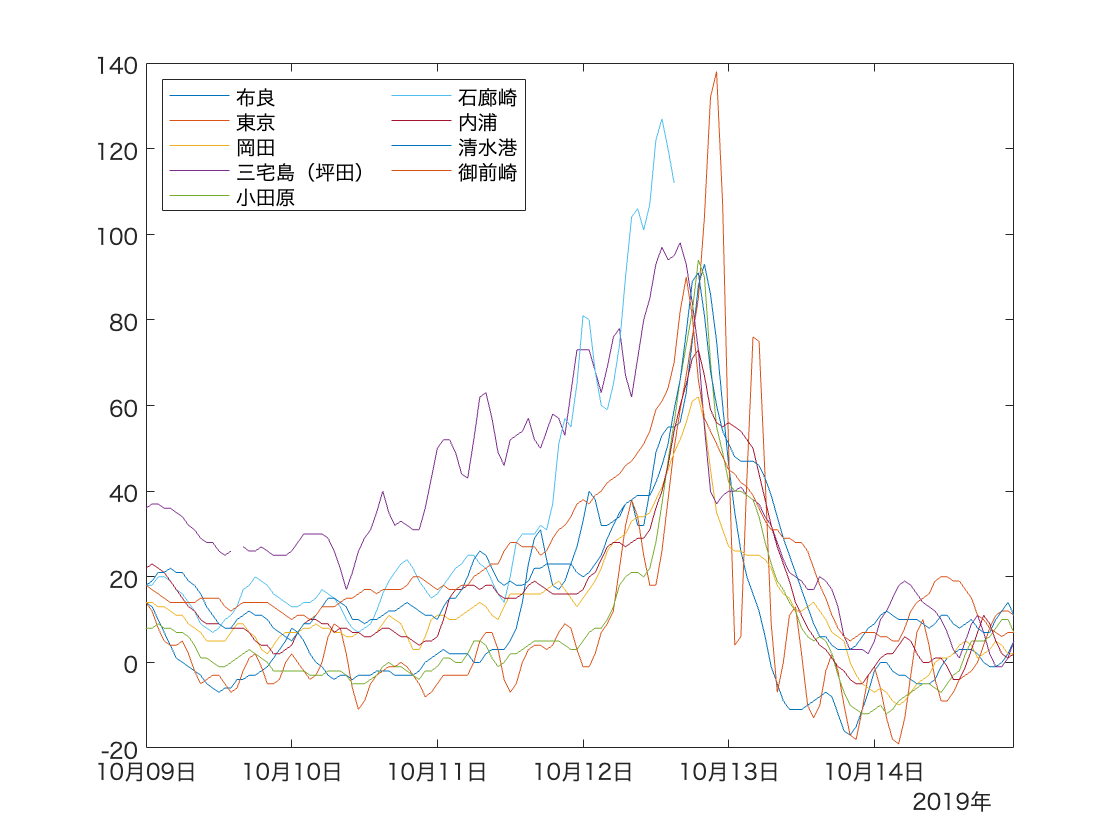

% 以下の9地点，2019年10月
tidegauge = JMAtide({'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 2019, 10);

% 潮位取得
tidegauge = tidegauge.loadssh;

% 潮位偏差取得
tidegauge = tidegauge.loadssha;

% plot - 潮位偏差
lines = tidegauge.plotssha;
xlim([tidegauge(1).Time(24*8)+hours(1), tidegauge(1).Time(24*14)])
legend(lines, {'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 'NumColumns',2, 'Location','NorthWest');

## CSVファイルへの出力

csvssh，csvsshaでそれぞれ潮位，潮位偏差を CSV ファイルとして出力します．

データの期間（年，月）が同じであれば，複数の地点を1つのファイルにまとめて出力します．

% ファイル出力前に，単位を cm → m へ
tidegauge = tidegauge.convertunit('m');

% CSVファイルとして出力
% 同一期間のため，全地点のデータを1つのファイルに格納
tidegauge.csvssh  % 潮位

sealevel_201910_MRTKOKMJODG9UCSMOM.dat


tidegauge.csvssha % 潮位偏差

sealevelanomaly_201910_MRTKOKMJODG9UCSMOM.dat


% 出力ファイルの確認 1行目〜10行目
dbtype sealevel_201910_MRTKOKMJODG9UCSMOM.dat 1:10

1     # time, 布良, 東京, 岡田, 三宅島（坪田）, 小田原, 石廊崎, 内浦, 清水港, 御前崎
2     20191001T0000,   -0.551,   -0.804,   -0.702,   -0.395,   -0.689,   -0.506,   -0.481,   -0.230,   -0.380
3     20191001T0100,   -0.401,   -0.754,   -0.612,   -0.325,   -0.579,   -0.536,   -0.491,   -0.290,   -0.400
4     20191001T0200,   -0.131,   -0.494,   -0.382,   -0.085,   -0.329,   -0.386,   -0.301,   -0.180,   -0.240
5     20191001T0300,    0.189,   -0.094,   -0.062,    0.235,    0.001,   -0.096,    0.039,    0.060,    0.050
6     20191001T0400,    0.489,    0.346,    0.258,    0.545,    0.321,    0.274,    0.419,    0.400,    0.390
7     20191001T0500,    0.679,    0.716,    0.498,    0.805,    0.551,    0.644,    0.759,    0.750,    0.720
8     20191001T0600,    0.749,    0.936,    0.598,    0.955,    0.651,    0.894,    0.989,    1.020,    0.940
9     20191001T0700,    0.669,    0.926,    0.578,    0.975,    0.611,    0.984,    1.069,    1.150,    1.020
10    20191001T0800,    0.459,    0.726,    0.428,    0.835,  